# 题目11：RGB空间绿色分割

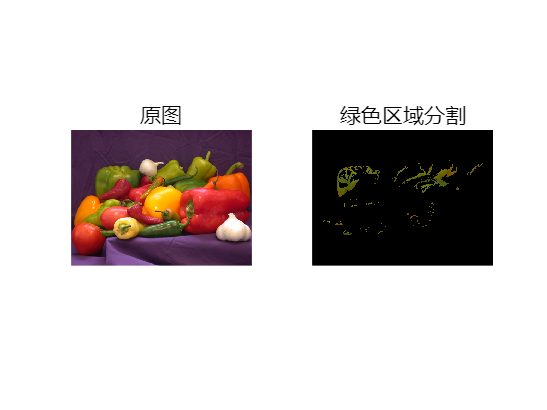

% 定义绿色区域的RGB阈值
green_threshold = [0.5, 0.3, 0.1]; % [R_max, G_min, B_max] 示例阈值

% 创建绿色掩膜
mask_green = img_rgb(:,:,1) < green_threshold(1) & ... % R通道 < 0.5
             img_rgb(:,:,2) > green_threshold(2) & ... % G通道 > 0.3
             img_rgb(:,:,3) < green_threshold(3);     % B通道 < 0.1

% 应用掩膜
img_green_seg = img_rgb .* mask_green;

% 显示结果
figure;
subplot(1,2,1), imshow(img_rgb), title('原图');
subplot(1,2,2), imshow(img_green_seg), title('绿色区域分割');